%1 Problem statement
 % On the basis of the mobile Specification like Battery power, 3G enabled , wifi ,Bluetooth, Ram etc we are predicting Price range of the mobile
%2 Training data_set link ==> https://www.kaggle.com/vikramb/mobile-price-prediction/data?select=train.csv

%3 Drive Link ==> https://drive.google.com/drive/folders/1S0G2f-CqLZu6FQnuGFXyoUCm-M7eSFIk?usp=sharing

%% Clear and Close Figures
clear ; close all; clc

%% Load Data
data =readmatrix('train.csv'); % read comma separated data
%training dataset
X = data(1:1500,1:20); 
y = data(1:1500, 21);

m = length(y);


% correlation plot
cr = corr(data);
disp("correlation matrix --> ")

correlation matrix --> 


disp(cr);

  Columns 1 through 7

    1.0000    0.0113    0.0115   -0.0418    0.0333    0.0157   -0.0040
    0.0113    1.0000    0.0214    0.0352    0.0036    0.0134    0.0412
    0.0115    0.0214    1.0000   -0.0013   -0.0004   -0.0431    0.0065
   -0.0418    0.0352   -0.0013    1.0000   -0.0291    0.0032   -0.0157
    0.0333    0.0036   -0.0004   -0.0291    1.0000   -0.0166   -0.0291
    0.0157    0.0134   -0.0431    0.0032   -0.0166    1.0000    0.0087
   -0.0040    0.0412    0.0065   -0.0157   -0.0291    0.0087    1.0000
    0.0341    0.0040   -0.0144   -0.0221   -0.0018   -0.0018    0.0069
    0.0018   -0.0086    0.0123   -0.0090    0.0236   -0.0165   -0.0342
   -0.0297    0.0362   -0.0057   -0.0247   -0.0134   -0.0297   -0.0283
    0.0314   -0.0100   -0.0052   -0.0171    0.6446   -0.0056   -0.0333
    0.0149   -0.0069   -0.0145   -0.0209   -0.0100   -0.0192    0.0104
   -0.0084   -0.0415   -0.0095    0.0143   -0.0052    0.0074   -0.0083
   -0.0007    0.0264    0.0034    0.0411    0.0151    

% figure
% corrplot(X,'testR','on');

VIF = diag(inv(cr))';
disp(VIF)

  Columns 1 through 7

    1.5026    1.0114    1.0070    1.0129    1.7191    1.5285    1.0117

  Columns 8 through 14

    1.0065    1.0141    1.0086    1.7208    1.5170    1.5059   11.3820

  Columns 15 through 21

    1.3563    1.3537    1.0105    1.5287    1.0064    1.0102   12.2897



% heatmap(X)

% Scale features and set them to zero mean
fprintf('Normalizing Features ...\n');

Normalizing Features ...



[X ,mu ,sigma] = featureNormalize(X);

mu = 	1.0e+03 *

    1.2409    0.0005    0.0015    0.0005    0.0043    0.0005    0.0326    0.0005    0.1410    0.0045    0.0099    0.6493    1.2491    2.1276    0.0123    0.0058    0.0111    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4393    0.0005    0.0008    0.0005    0.0044    0.0005    0.0182    0.0003    0.0352    0.0023    0.0061    0.4439    0.4288    1.0972    0.0042    0.0043    0.0054    0.0004    0.0005    0.0005



fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [-1 -1], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 0], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 0], y = -1 
 x = [0 1], y = -2 
 x = [-1 1], y = 1 
 x = [-1 1], y = -1 
 x = [1 -1], y = 1 
 x = [1 1], y = -0 
 x = [-1 -1], y = 1 
 x = [2 0], y = 1 
 x = [-1 -1], y = 1 
 x = [1 -1], y = 2 
 x = [-2 1], y = -1 
 x = [1 -1], y = 1 
 x = [0 1], y = 0 
 x = [0 -1], y = 1 
 x = [1 0], y = -0 
 x = [-1 -0], y = 1 
 x = [1 -1], y = 2 
 x = [-1 1], y = 1 
 x = [-1 -1], y = -1 
 x = [-1 1], y = -0 
 x = [1 -0], y = 1 
 x = [1 1], y = 1 
 x = [1 -0], y = 1 
 x = [-1 -1], y = 2 
 x = [1 1], y = -0 
 x = [-1 2], y = 1 
 x = [1 0], y = 0 
 x = [-1 1], y = 1 
 x = [-0 -1], y = -1 
 x = [-1 1], y = 1 
 x = [1 -1], y = 1 
 x = [1 -1], y = -1 
 x = [1 -0], y = -1 
 x = [-1 1], y = 1 
 x = [-2 -0], y = 1 
 x = [1 -1], y = 1 
 x = [-1 -0], y = 1 
 x = [-1 -1], y = 1 
 x = [1 -1], y = 0 
 x = [-1 -0], y = 1 
 x = [-1 1], y = -0 
 x = [2 0], y = -1 
 x = [-1 1], y = 0 
 x = [1 1], y = 1 
 x = [-1 1], y = 3 
 

% Add intercept term to X
X = [ones(m, 1) X];


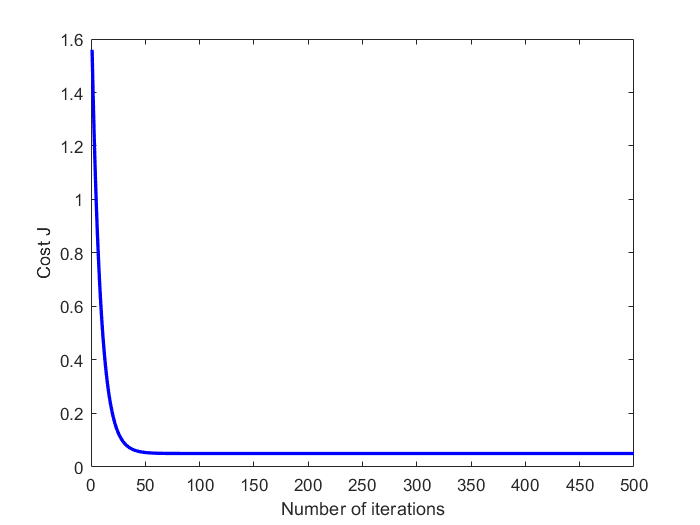

%% ================ Part 2: Gradient Descent ================
alpha = 0.06;
num_iters = 500;

theta = zeros(length(X(1,:)), 1);
[theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');

Theta computed from gradient descent: 


fprintf(' %f \n', theta);

 1.504667 
 0.219331 
 -0.000582 
 -0.011160 
 -0.007689 
 0.004526 
 -0.004561 
 0.010768 
 -0.005848 
 -0.029842 
 0.000323 
 0.000541 
 0.126139 
 0.118608 
 1.036136 
 0.003931 
 -0.004057 
 -0.002001 
 0.017500 
 -0.004655 
 -0.007105 


% running for training data
testData = readmatrix('train.csv');
t2 = testData(1:1500,1:20);

priceArr = zeros(1500,1);
for i = 1:1:1500
priceArr(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end
disp("training Accuracy percentage");

training Accuracy percentage


acc = mean(double(int64(priceArr) == y))*100;
disp(acc);

   88.8667



% running for CV data
X_CV = data(1501:1800,1:20);
y_CV = data(1501:1800,21);
t2 = X_CV(:,1:20);
priceArr2 = zeros(300,1);
for i = 1:1:300
priceArr2(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end

disp("Predicted price for test data")

Predicted price for test data


acc = mean(double(int64(priceArr2) == y_CV))*100;
disp(acc);

   88.3333



% running for test data
X_test = data(1801:2000,1:20);
y_test = data(1801:2000,21);

t2 = X_test(:,1:20);
priceArr3 = zeros(200,1);
for i = 1:1:200
priceArr3(i) = [1 (t2(i,1)-mu(1))/sigma(1) (t2(i,2)-mu(2))/sigma(2) (t2(i,3)-mu(3))/sigma(3) (t2(i,4)-mu(4))/sigma(4) (t2(i,5)-mu(5))/sigma(5) (t2(i,6)-mu(6))/sigma(6) (t2(i,7)-mu(7))/sigma(7) (t2(i,8)-mu(8))/sigma(8) (t2(i,9)-mu(9))/sigma(9) (t2(i,10)-mu(10))/sigma(10) (t2(i,11)-mu(11))/sigma(11) (t2(i,12)-mu(12))/sigma(12) (t2(i,13)-mu(13))/sigma(13) (t2(i,14)-mu(14))/sigma(14) (t2(i,15)-mu(15))/sigma(15) (t2(i,16)-mu(16))/sigma(16) (t2(i,17)-mu(17))/sigma(17) (t2(i,18)-mu(18))/sigma(18) (t2(i,19)-mu(19))/sigma(19) (t2(i,20)-mu(20))/sigma(20) ]*theta;    
end

disp("Predicted price for test data")

Predicted price for test data


acc = mean(double(int64(priceArr3) == y_test))*100;
disp(acc);

   88.5000



% train cost
train_cost = computeCostMulti(X,y,theta);
disp(train_cost);

    0.0505



% corss validation cost
m_CV = length(y_CV);
[X_CV ,~ ,~] = featureNormalize(X_CV);

mu = 	1.0e+03 *

    1.2470    0.0005    0.0015    0.0005    0.0046    0.0006    0.0306    0.0005    0.1379    0.0046    0.0100    0.6385    1.2774    2.1760    0.0125    0.0060    0.0111    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4348    0.0005    0.0008    0.0005    0.0045    0.0005    0.0176    0.0003    0.0361    0.0023    0.0061    0.4617    0.4414    1.0288    0.0042    0.0045    0.0056    0.0004    0.0005    0.0005


X_CV = [ones(m_CV, 1) X_CV];

CV_cost = computeCostMulti(X_CV,y_CV,theta);
disp(CV_cost);

    0.0585



% test cost
m_test = length(y_test);
[X_test ,~ ,~] = featureNormalize(X_test);

mu = 	1.0e+03 *

    1.2076    0.0005    0.0015    0.0005    0.0040    0.0005    0.0303    0.0005    0.1383    0.0046    0.0101    0.6235    1.2310    2.0208    0.0117    0.0054    0.0101    0.0008    0.0005    0.0005


sigma = 	1.0e+03 *

    0.4480    0.0005    0.0008    0.0005    0.0040    0.0005    0.0187    0.0003    0.0357    0.0022    0.0060    0.4157    0.4444    1.0708    0.0042    0.0043    0.0057    0.0004    0.0005    0.0005


X_test = [ones(m_test, 1) X_test];
test_cost = computeCostMulti(X_test,y_test,theta);
disp(test_cost);

    0.0611



r = Rsq(X,y,theta);
disp("R squared value ");

R squared value 


disp(r);

    0.9196

